# Parabolic Equation: Explicit

## 

## Check for stability

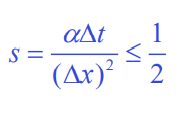

%Put in appropriate values that question gives you
alpha=0.75;
delta_x=0.2;
delta_t=0.02;

%Outputs give you s value and whether or not this is stable
s=alpha*delta_t/delta_x^2

s = 0.3750

if s<=0.5
    disp('Stable')
else
    disp('Unstable')
end

Stable


## Boundary Conditions

%Put in question's x and t ranges
x_start=0;
x_end=1;
t_start=0;
t_end=0.1;

n_x=int16((x_end-x_start)/delta_x+1);
n_t=int16((t_end-t_start)/delta_t+1);

boundary_x=zeros(1,n_x); 
boundary_t_1=zeros(1,n_t);
boundary_t_2=zeros(1,n_t);

%Put in boundary conditions 
boundary_x=[0,0.04,0.16,0.36,0.64,1]; %Initial temperatures when t=0
boundary_t_1=[0,0,0,0,0,0]; %Beginning of rod
boundary_t_2=[1,1,1,1,1,1]; %End of rod

## Solving for T

T=zeros(n_t,n_x);
T(1,:)=boundary_x;
T(:,1)=boundary_t_1;
T(:,n_x)=boundary_t_2;

for k=2:n_t
    for i=2:n_x-1
        T(k,i)=s*T(k-1,i+1)+(1-2*s)*T(k-1,i)+s*T(k-1,i-1);
    end
end

%Answers (vertical is t, horizontal is x)
temperature=table(T(:,1),T(:,2),T(:,3),T(:,4),T(:,5),T(:,6))

temperature = 6×6 table
    Var1     Var2       Var3       Var4       Var5      Var6
    ____    _______    _______    _______    _______    ____

     0         0.04       0.16       0.36       0.64     1  
     0         0.07       0.19       0.39       0.67     1  
     0      0.08875       0.22       0.42    0.68875     1  
     0      0.10469    0.24578    0.44578    0.70469     1  
     0      0.11834    0.26787    0.46787    0.71834     1  
     0      0.13004     0.2868     0.4868    0.73004     1  
